# SAMPLE OF THE USE OF class_soil_Vereecken (Model: Vereecken, H. et al 1989)

## INPUTS:

Grain Size Distribution:

%       Particle Diameter       Aggregated Particle Volume passing
%       [m]                     [m3·m-3]
GSD = [ 0                       ,0;...
        2.00000000000000e-06    ,0.0200000000000000;...
        5.00000000000000e-05    ,0.130000000000000;...
        0.000106000000000000    ,0.256000000000000;...
        0.000250000000000000    ,0.743000000000000;...
        0.000500000000000000    ,0.916000000000000;...
        0.00100000000000000     ,0.985000000000000;...
        0.00200000000000000     ,0.997000000000000];

Porosity:

npor = 0.45;    

Water Retention Curve (optional, only for comparison purposes):

%       Pore Diameter           Aggregated Pore Volume
%       [m]                     [m3·m-3]
WRC = [ 0,                      0.361500000000000;...
        0.200000000000000      ,0.324000000000000;...
        0.300000000000000      ,0.265500000000000;...
        0.400000000000000      ,0.194500000000000;...
        0.500000000000000      ,0.160000000000000;...
        0.700000000000000      ,0.111000000000000;...
        1                      ,0.0795000000000000;...
        2                      ,0.0570000000000000;...
        4.30000000000000       ,0.0445000000000000;...
        6.40000000000000       ,0.0365000000000000;...
        10.5000000000000       ,0.0265000000000000];    

Model for m Van-Genuchten paramenter and Level of PTF (1 or 2) (see Vereecken, 1989):

model = 4; 
level = 1;

## CONSTRUCTION OF THE INSTANCE OF THE AP81 MODEL:

soil = class_soil_Vereecken(...
    'GSD',GSD,...
    'WRC',WRC,...
    'npor',npor,...
    'Model',model, ...
    'Level',level);

## EXAMPLES OF POSSIBLE OUTPUTS OF THE MODEL:

Grain Size in the GSD at 20% (D20) in [m]: 

disp(soil.Dg_FVg_from_GSD(0.2));

   8.2051e-05



Pore Size for the quantile 40% [m] (for the aggregated pore volume of 40% in the PSD) predicte from the GSD: 

disp(soil.Dp_Dg_from_GSD(soil.Dg_FVg_from_GSD(0.4)));

   4.5761e-05



Pore Size corresponding to the Particle diameter of 1E-4 [m] predicted with the model:

disp(soil.Dp_Dg_from_GSD(1E-4));

   2.7690e-05



 Pore Volume for the Pore size of 1E-4[m], on the PSD predicted with the model [per unit]:

disp(soil.FVp_Dp_from_GSD(1E-4));

    0.6773



 Pore Volume for the Pore size of 1E-5[m], on the PSD from the measured WRC:

disp(soil.FVp_Dp_from_WRC(1.0E-4));

    0.7255



Volumetric Water content for a suction of 1E-7[m] predicted by the model:

disp(soil.th_pp_from_GSD(1E-4));

    0.4745



Suction [m] for a volumetric water content of 0.35 m3/m3:

disp(soil.pp_th_from_GSD(0.35));

    0.2537



Suction [m] prediction for a relative saturation of 60%:

disp(soil.pp_Se_from_GSD(0.60));

    0.3700



disp(soil.pp_Se_from_WRC(0.60));

    0.2561



## PLOT OF THE PORE SIZE DISTRIBUTION:

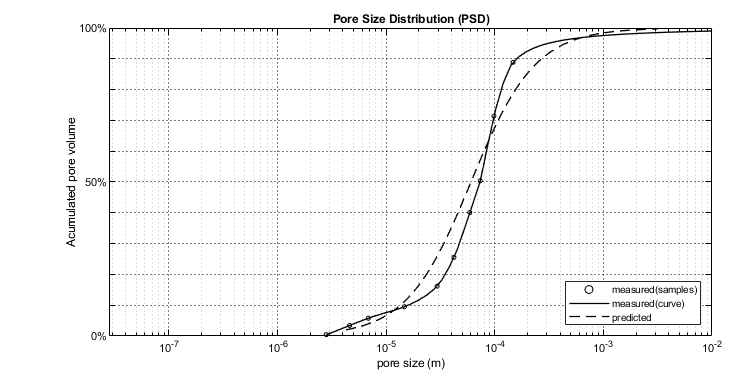

soilplot = class_soil_PLOT(soil);
soilplot = soilplot.show_PSD('Pore Size Distribution (PSD)');
soilplot = soilplot.add_PSD_from_GSD(soil,'--',1,[0,0,0]);
legend({'measured(samples)','measured(curve)','predicted'},'Location','Southeast');

## PLOT THE WATER RETENTION CURVE

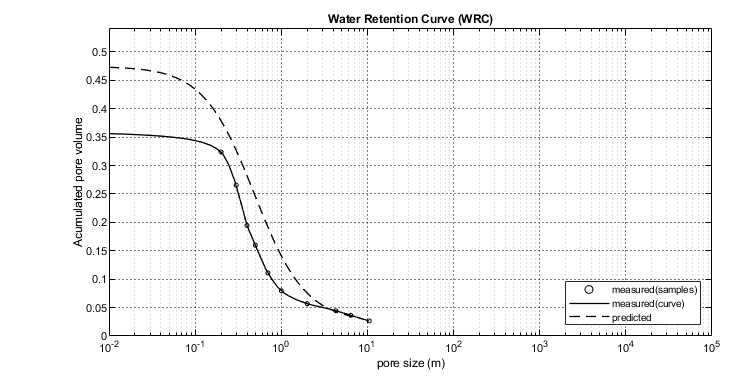

soilplotWRC = class_soil_PLOT(soil);
soilplotWRC = soilplotWRC.show_WRC('Water Retention Curve (WRC)');
soilplotWRC = soilplotWRC.add_WRC_from_GSD(soil,'--',1,[0,0,0]);
legend({'measured(samples)','measured(curve)','predicted'},'Location','Southeast');

clear('model','GSD','npor','WRC');
